%% Projeto Computacional
% Primeira estrutura de discretização

clear
clc
close all

# 1. Parâmetros físicos

Lx = 1;             % largura [m]
Ly = 1;             % comprimento [m]
Lz = 1;             % altura [m]
rho = 917;          % densidade do gelo [kg/m3]
cp = 2100;          % Calor específico do gelo [J/(kg.K)]
k = 2.22;           % condutividade térmica do gelo [W/(m⋅K)]
T0 = -10;           % Temperatura inicial do gelo [°C]
Tamb = 20;          % Temperatura do ambiente [°C]
l = 334000;         % Calor latente [J/kg]
h = 15;             % Coeficiente de convecçao de 15-25 [W/(m^2⋅K)]
delta_T = 273.15;   % intervalo numérico de transição de fase [K]

# 2.Domínio computacional

Nx = 10;            % numero de pontos no eixo x
Ny = 10;            % numero de pontos no eixo y
Nz = 10;            % numero de pontos no eixo z
delta_x = 0.1;      % intervalo entre pontos em x
delta_y = 0.1;      % intervalo entre pontos em y
delta_z = 0.1;      % intervalo entre pontos em z
delta_t = 0.1;      % intervalo temporal
t0 = 0;             % instante inicial
tf = 15;            % instante final
t = t0:delta_t:tf;  % vetor de pontos no dominio do tempo

# 3.Geração da malha

Inicialmente: Malha uniforme

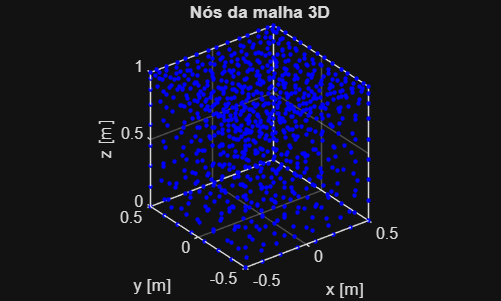

%TODO colocar a mesh em apenas um quarto e dps espelhar
model = createpde();

geo = multicuboid(Lx, Ly, Lz);
model.Geometry = geo;

%% 2. IDs da face, arestas e vertices superiores
topFace = 2;
topEdges = [5 6 7 8];
topVertices = [5 6 7 8];

%% 3. Gerar a malha refinada
mesh = generateMesh(model, ...
    'Hmax', 0.15, ...
    'Hmin', 0.04, ...
    'Hface', {topFace, 0.08}, ...
    'Hedge', {topEdges, 0.06}, ...
    'Hvertex', {topVertices, 0.04}, ...
    'Hgrad', 1.5, ...
    'GeometricOrder', 'linear');

nodes = mesh.Nodes;

figure
plot3(nodes(1,:), nodes(2,:), nodes(3,:), ...
    'b.', 'MarkerSize', 8);

xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')

title('Nós da malha 3D')
axis equal
grid on
box on
view(3)

# 4.Variáveis e incógnitas

Incognitas: T (em cada ponto da malha tri-dimensional)

Variáveis: X, Y, Z, t

# 5.Equações discretizadas

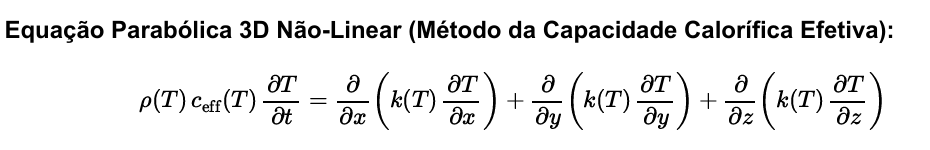

# 6.Condições de fronteira

Condições iniciais: T(x, y, z, 0) = T0 ≤ 0 ∘C (ex.: T0 = −10 ∘C ou − 5 ∘C)

Opção 1 (Robin): Convecção de calor com o ambiente quente: −k(T) ∂T ∂n = h (T − Tamb)

%% Condições térmicas

% 1. Equação de condução térmica
specifyCoefficients(model, 'm', 0, 'd', rho*cp, 'c', k, 'a', 0, 'f', 0);

% 2. Condição de fronteira convectiva
% Aplicada às seis faces do cubo
applyBoundaryCondition(model, 'mixed', 'Face', 1:6, 'h', h, 'r', h*Tamb);

% 3. Condição inicial
setInitialConditions(model, T0);

% 4. Resolver ao longo do tempo
result = solvepde(model, t);

% Temperatura calculada em todos os nós
T = result.NodalSolution;

# 7.Resoluçao Numérica

# 8.Verificação

%TODO

Desenhar malha cubica

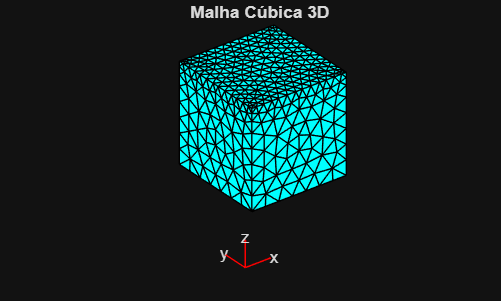

%% 4. Visualizar a malha
figure
pdemesh(mesh);

title('Malha Cúbica 3D')
xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')

axis equal
view(3)
grid on


fprintf('Numero total de nos: %d\n', size(mesh.Nodes,2));

Numero total de nos: 839


fprintf('Numero de elementos: %d\n', size(mesh.Elements,2));

Numero de elementos: 3389
